clc; clear;

**Divided Differences**

f = @(x) -2*x.^3 + 15*x.^2 - 7*x - 5;

xvals = [0, 1, 3];

[dd, fvals] = newtondd(f, xvals);

disp('Divided Differences (Leftmost Column):');

Divided Differences (Leftmost Column):


disp(dd);

    -5     6     7



disp('Function Values:');

Function Values:


disp(fvals);

    -5     1    55




y = function1([1,2,3,4])

y =     -1     0     1   512


**Horner and Divided Differences Test**

test_eval = [0,1,2,3,5,6,7,8];
f_test_true = f(test_eval);
f_horner = horner(dd, xvals, test_eval);

disp('L1 Error:')

L1 Error:


disp(sum(abs(f_horner - f_test_true)))

        1160



**Orderings Test**

arr = [3, 1, 4, 2];

leja = order(arr,'leja')

leja =      4     1     3     2


ascend = order(arr,'ascend')

ascend =      1     2     3     4


descend = order(arr,'descend')

descend =      4     3     2     1


**Product Polynomial Form Test**

poly = polyProduct(1,arr,[1,2,3,4,0,5,-1]);
disp(poly);

     0     0     0     0    24    24   120



**Barycentric 1 Test**

f = @(x) abs(x)

f = function_handle with value:
    @(x)abs(x)


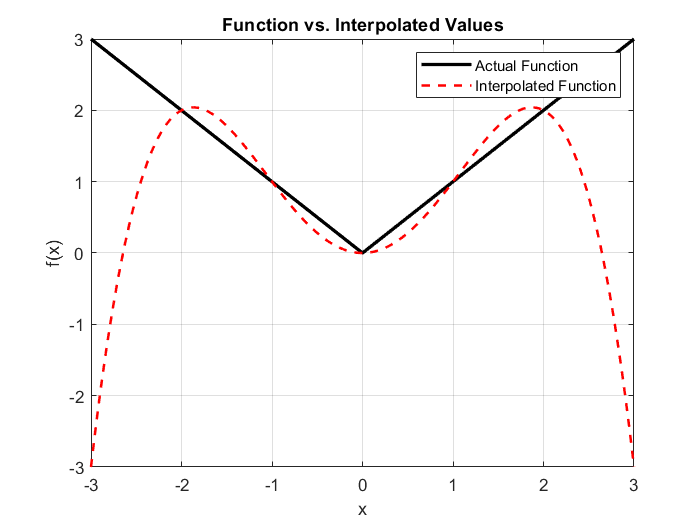

nodes = [-2,-1,0,1,2];

xx = linspace(-3,3,1000);
ff = f(xx);

[gamma, fbary1] = barycentric1(f,5,nodes);
[evals, kappa, kappa_one] = bary1Eval(xx,fbary1,nodes,gamma);

figure;
plot(xx, ff, 'k-', 'LineWidth', 2);
hold on;
plot(xx, evals, 'r--', 'LineWidth', 1.5);
xlabel('x');
ylabel('f(x)');
title('Function vs. Interpolated Values');
legend('Actual Function', 'Interpolated Function');
grid on;
hold off;


disp(max(kappa))

   27.0000



lebesgue_const = max(kappa_one)

lebesgue_const = single
31

**Berrut and Trefethen Experiment**

fun = @(z) abs(z)+0.5*z-z.^2;

n =20;
nodes2 = chebyshev2(-1,1,n);
disp(size(nodes2))

     1    20



[betas,f] = barycentric2(fun,n,'cheby2');
disp(size(f))

     1    20



disp(size(betas))

    20     1



xx=linspace(-1,1,1000);
ft = fun(xx);

ff = bary2Eval(xx,f,nodes2,betas,n);

xvals = 1×1000 single row vector
   -1.0000   -0.9980   -0.9960   -0.9940   -0.9920   -0.9900   -0.9880   -0.9860   -0.9840   -0.9820   -0.9800   -0.9780   -0.9760   -0.9740   -0.9720   -0.9700   -0.9680   -0.9660   -0.9640   -0.9620   -0.9600   -0.9580   -0.9560   -0.9540   -0.9520   -0.9499   -0.9479   -0.9459   -0.9439   -0.9419   -0.9399   -0.9379   -0.9359   -0.9339   -0.9319   -0.9299   -0.9279   -0.9259   -0.9239   -0.9219   -0.9199   -0.9179   -0.9159   -0.9139   -0.9119   -0.9099   -0.9079   -0.9059   -0.9039   -0.9019


n = single
20

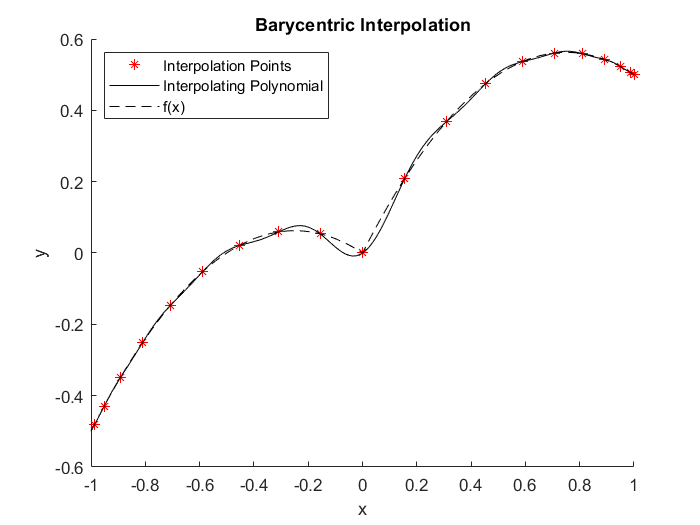


figure;
hold on;
plot(nodes2, f, '*r', 'DisplayName', 'Interpolation Points');  % red asterisks for nodes
plot(xx, ff, '-k', 'DisplayName', 'Interpolating Polynomial'); % solid black line
plot(xx, ft, '--k', 'DisplayName', 'f(x)');                     % dashed black line
hold off;

xlabel('x');
ylabel('y');
title('Barycentric Interpolation');
legend('Location', 'northwest');  % places legend in the top-left corner inside the axes

**Task 2**

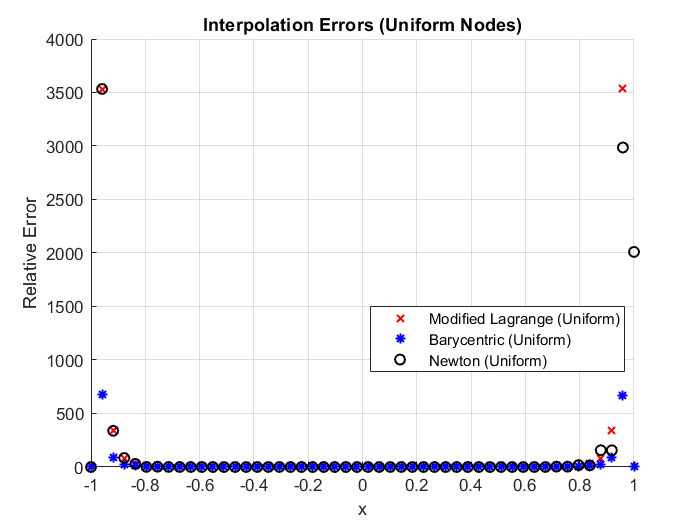

% Interval of Interest
a=-1;
b= 1;

n=30;
% Nodes
n_uniform = order(uniform(a,b,n),'ascend');
n_cheby1 = order(chebyshev1(a,b,n),'ascend');
n_cheby2 = order(chebyshev2(a,b,n),'ascend');

% Divided Differences for each kind of node
[dd_uniform, f_uniform] = newtondd(@function4,n_uniform);
[dd_cheby1, f_cheby1] = newtondd(@function4,n_cheby1);
[dd_cheby2, f_cheby2] = newtondd(@function4,n_cheby2);

% Evaluating the actual function at test points
xx = linspace(a,b,50);
ff = function4(xx);

% Evaluating Newton interpolating polynomails at test points 
ff_uniform = horner(dd_uniform, n_uniform, xx);
ff_cheby1 = horner(dd_cheby1, n_cheby1, xx);
ff_cheby2 = horner(dd_cheby2, n_cheby2, xx);


% Evaluating Barycentric 1 Coefficients and then at test points
[gamma, f_bary1_uniform] = barycentric1(@function4,n,n_uniform);
[ff_bary1, kappa,kappa_one] = bary1Eval(xx,f_bary1_uniform,n_uniform,gamma);

% Evaluating Barycentric 2 Coefficients and then at test points
[beta, f_bary2_uniform] = barycentric2(@function4,n,'uniform');
ff_bary2 = bary2Eval(xx,f_bary2_uniform,n_uniform,beta,n);



% Evaluating the absolute errors for each method for the uniform nodes
abs_error_bary1 = abs(ff_bary1 - ff);
abs_error_bary2 = abs(ff_bary2 - ff);
abs_error_newton = abs(ff_uniform - ff); % Newton with uniform nodes

% Evaluating the absolute errors for each method for the uniform nodes
abs_error_bary1_uniform = abs(ff_bary1 - ff) ./ abs(ff);
abs_error_bary2_uniform = abs(ff_bary2 - ff) ./ abs(ff);
abs_error_newton_uniform = abs(ff_uniform - ff) ./ abs(ff);

% Evaluating the absolute errors for each method for the Chebyshev1 nodes
abs_error_bary1_cheby1 = abs(ff_bary1 - ff) ./ abs(ff);
abs_error_bary2_cheby1 = abs(ff_bary2 - ff) ./ abs(ff);
abs_error_newton_cheby1 = abs(ff_cheby1 - ff) ./ abs(ff);

%% **Plot 1: Uniform Nodes**
figure;
hold on;

plot(xx, abs_error_bary1_uniform, 'rx', 'MarkerSize', 6, 'LineWidth', 1.2, 'DisplayName', 'Modified Lagrange (Uniform)');
plot(xx, abs_error_bary2_uniform, 'b*', 'MarkerSize', 6, 'LineWidth', 1.2, 'DisplayName', 'Barycentric (Uniform)');
plot(xx, abs_error_newton_uniform, 'ko', 'MarkerSize', 6, 'LineWidth', 1.2, 'DisplayName', 'Newton (Uniform)');

xlabel('x');
ylabel('Relative Error');
title('Interpolation Errors (Uniform Nodes)');
legend('Location', 'best');
grid on;
hold off;

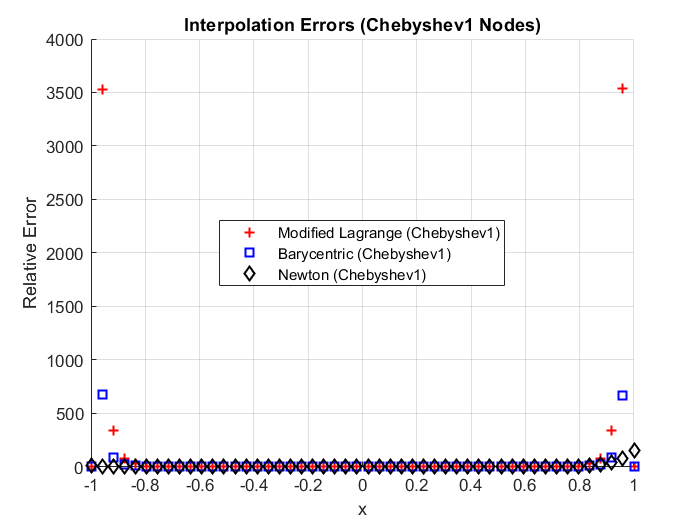


%% **Plot 2: Chebyshev1 Nodes**
figure;
hold on;

plot(xx, abs_error_bary1_cheby1, 'r+', 'MarkerSize', 6, 'LineWidth', 1.2, 'DisplayName', 'Modified Lagrange (Chebyshev1)');
plot(xx, abs_error_bary2_cheby1, 'bs', 'MarkerSize', 6, 'LineWidth', 1.2, 'DisplayName', 'Barycentric (Chebyshev1)');
plot(xx, abs_error_newton_cheby1, 'kd', 'MarkerSize', 6, 'LineWidth', 1.2, 'DisplayName', 'Newton (Chebyshev1)');

xlabel('x');
ylabel('Relative Error');
title('Interpolation Errors (Chebyshev1 Nodes)');
legend('Location', 'best');
grid on;
hold off;

% Infinity-norm errors for the polynomials
infinity_error_bary1 = max(abs_error_bary1) ./ abs(ff);
infinity_error_bary2 = max(abs_error_bary2) ./ abs(ff);
infinity_error_newton  = max(abs_error_newton) ./ abs(ff);

% Evaluating the condition numbers and the Lebesgue and H_n constants
kappa = kappa ./ abs(ff);
lebesgue_const = max(kappa_one)

lebesgue_const = single
1.4880e+06

script_H_n = max(kappa)

script_H_n = single
17097448

\begin{table}[h]
\centering
\begin{tabular}{|c|c|c|}
\hline
Node Type & Lebesgue Constant & H_n \\
\hline
uniform & 3325811.5000 & 53.7101 \\
chebyshev1 & 493.0692 & 0.0034 \\
chebyshev2 & 59.0000 & 0.0024 \\
\hline
\end{tabular}
\caption{Conditioning Metrics for function4}
\label{tab:function4-conditioning}
\end{table}



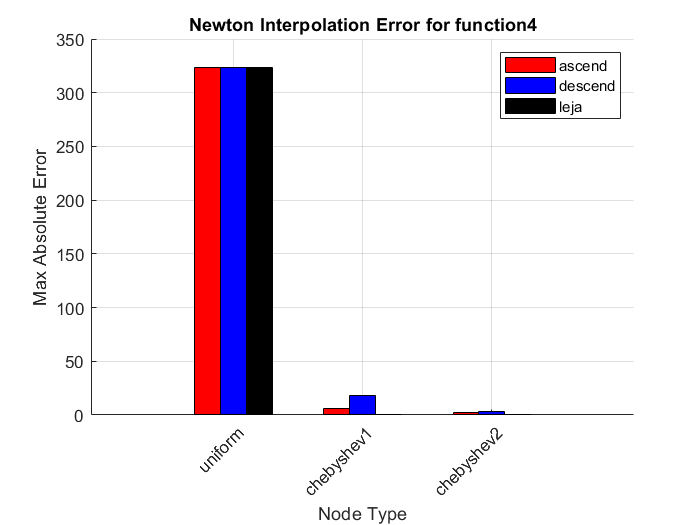

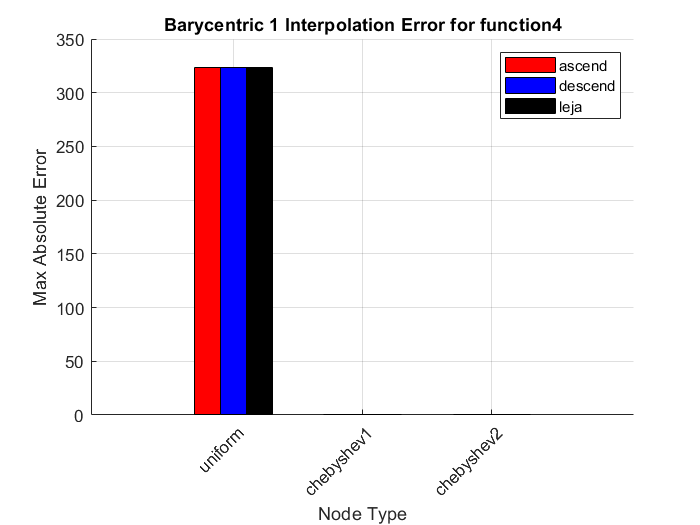

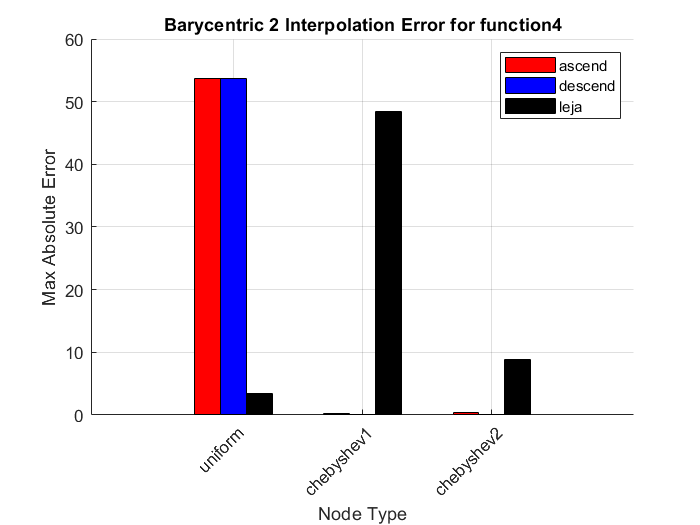

statistics(@function4,-1,1,30)